# Fourier Series Magic

Fourier series expresses a periodic function, f(t), in terms of an infinite sum of sines and cosines. This examples shows how a square wave with a fundamental period of T can be expressed in terms of summation of sines and cosines, like MAGIC! 

*Copyright © Angora Tutor, 2020. All rights reserved.*

## Setup the Time Vector

In MATLAB, there is no continuous time signals. We have to digitize the signals and formulas to find an approximate solution. The accuracy of our solution will depend on how finely we sample our signals. So, let's first create a sampled time vector that covers $0\le t<T$. $T_s$ is the sampling period. Notice the < sign. Because $t<T$, `t` vector has to stop just before $T$. One sample before $T$ is $T-T_s$.

T = 2;              % Period of f(t) in seconds
Nmax = 100;         % Maximum supported N value
Ts = T / (2*Nmax);   % Sampling period in seconds / sample (Complies with Nyquist for Nmax=100)
t = 0:Ts:T-Ts       % Time vector in seconds

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


## Setup the f(t) Function

f(t) is a square wave with period $T=2$. Define its amplitude is $A$. In this example, we will use $A=2$.See Appendix A to learn more about *logical indexing* in MATLAB.

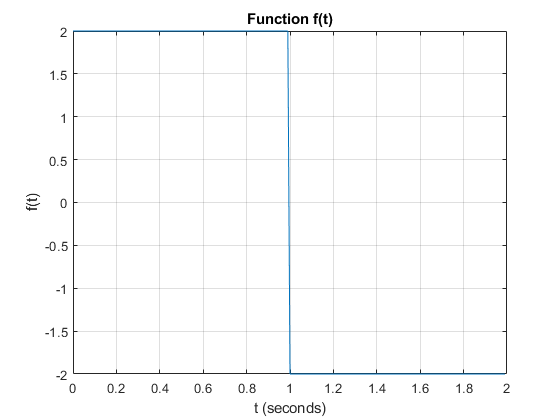

A = 2;
f = zeros(size(t));
f(t < (T/2)) = A;           % Set f(t) to A for t values less than T/2.
f((t>=(T/2)) & (t<T)) = -A; % Set f(t) to -A for t values greater than T/2 and less than T

plot(t,f)
title('Function f(t)')
xlabel('t (seconds)')
ylabel('f(t)')
grid on

## Fourier Coefficients or Analysis with Real Coefficients

Use sine and cosine functions to decompose a periodic signal into its harmonics. The coefficients are real valued. The analysis formula for real cofficients is as follows:


$$\begin{array}{l}
a_n =\frac{2}{T}\int_0^T f\left(t\right)\cos \left(\frac{2\pi \textrm{tn}}{T}\right)\textrm{dt}\\
b_n =\frac{2}{T}\int_0^T f\left(t\right)\sin \left(\frac{2\pi \textrm{tn}}{T}\right)\textrm{dt}
\end{array}$$


### Setup Cosine and Sine Terms

Change the value of n and hit tab to see how $a_n$ and $b_n$ change.

n = 10

n = 10

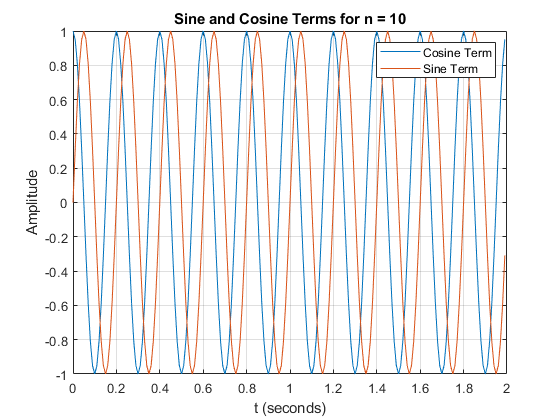

cosTerm = cos(2*pi*t*n/T);
sinTerm = sin(2*pi*t*n/T);

plot(t,cosTerm)
hold on
plot(t,sinTerm)
hold off
grid on
xlabel('t (seconds)')
ylabel('Amplitude')
legend('Cosine Term', 'Sine Term')
title(sprintf('Sine and Cosine Terms for n = %d', n))

### Calculate Fouier Coefficients for N Harmonics

Now that we have al the ingredients, let's cook! Calculate $a_n$ and $b_n$ for $N$ harmonics. That is just the fency way of saying "calculate $a_n$ and $b_n$ for `n=0:N`". Note that, `n` starts from 0. In MATLAB, array indices start from 1. So, we cannot use `n` as an index for `a` and `b` vectors. So, we use a seperate index variable, `idx`, where we initialize to 1 and increment at every iteration of the for-loop.

When sampled, the integration turns into a summation. Note that, $\textrm{dt}$ turns becomes $T_s$.


$$\begin{array}{l}
a_n =\frac{2T_s }{T}\sum_t f\left(t\right)\cos \left(\frac{2\pi \textrm{tn}}{T}\right)\\
b_n =\frac{2T_s }{T}\sum_t f\left(t\right)\sin \left(\frac{2\pi \textrm{tn}}{T}\right)
\end{array}$$


Change the value of N and hit tab to observe how coefficients and synthesis results changes.

N = 30    % Number of harmonics

N = 30

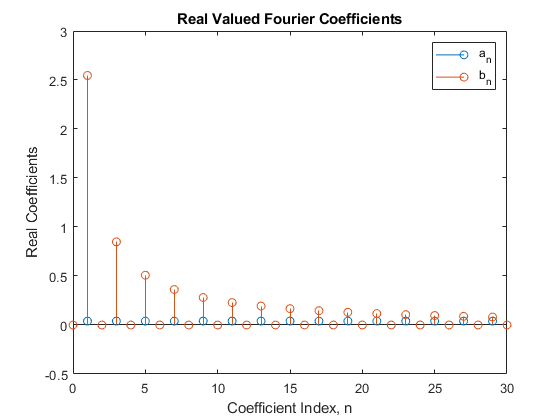

idx = 1;                    % Index for a and b vectors
a = zeros(1,N+1);           % Preallocate for speed
b = zeros(1,N+1);           % Preallocate for speed
for n = 0:N
    cosTerm = cos(2*pi*t*n/T);
    sinTerm = sin(2*pi*t*n/T);
    a(idx) = (2*Ts/T)*sum(f .* cosTerm);    % Integrate from t = 0 to T
    b(idx) = (2*Ts/T)*sum(f .* sinTerm);    % Integrate from t = 0 to T
    idx = idx + 1;
end

stem(0:N, a)
hold on
stem(0:N, b)
hold off
xlabel('Coefficient Index, n')
ylabel('Real Coefficients')
legend('a_n', 'b_n')
title('Real Valued Fourier Coefficients')

### Fourier Series or Synthesis with Real Coefficients

We can now write the Fourier series representation of the function f(t), which is also known as synthesis. 


$$f_s \left(t\right)=\frac{a_0 }{2}+\sum_{n=0}^N \left(a_n \cos \left(\frac{2\pi \textrm{nt}}{T}\right)+b_n \sin \left(\frac{2\pi \textrm{nt}}{T}\right)\right)$$


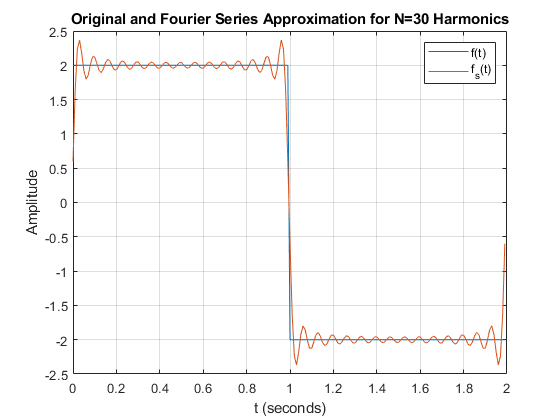

% Initialize f_s with a_0, which is the first value in a vector
f_s = (a(1)/2)*ones(size(t));
for n=1:N
    cosTerm = cos(2*pi*t*n/T);
    sinTerm = sin(2*pi*t*n/T);
    % Accumulate f_s with the nth term. Since n starts from 0, we use index
    % n+1 in MATLAB, which uses 1-based indexing.
    f_s = f_s  + a(n +1)*cosTerm + b(n +1)*sinTerm;
end

plot(t,f)
hold on
plot(t,f_s)
hold off
grid on
xlabel('t (seconds)')
ylabel('Amplitude')
legend('f(t)', 'f_s(t)')
title(sprintf('Original and Fourier Series Approximation for N=%d Harmonics',N))

## Fourier Coefficients or Analysis with Complex Coefficients

We can do the same using complex coefficients. For this, we will use complex exponentials. 


$$c_n =\frac{1}{T}\int_0^T f\left(t\right)e^{\left(\frac{-j2\pi \textrm{tn}}{T}\right)} \textrm{dt}$$


Change n and hit tab to see its effect.

### Setup Exponential Terms

n = 5

n = 5

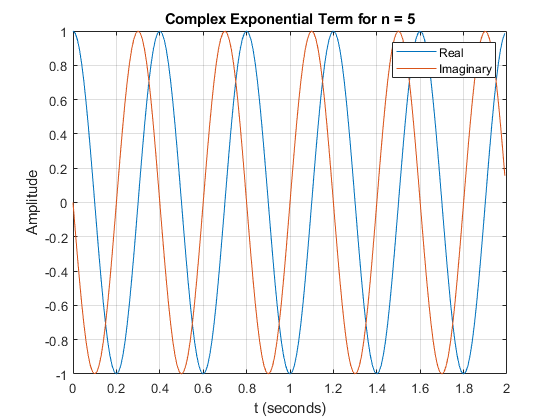

expTerm = exp(-1i*2*pi*t*n/T);

plot(t,real(expTerm))
hold on
plot(t,imag(expTerm))
hold off
grid on
xlabel('t (seconds)')
ylabel('Amplitude')
legend('Real', 'Imaginary')
title(sprintf('Complex Exponential Term for n = %d', n))

### Calculate Fouier Coefficients for N Harmonics

When working with complex coefficients, we need to consider both positve and negative harmonics. So, for `N` harmonics, we need `n=-N:N`. Change N and hit tab to see its effect. See Appendix B for a more efficient implementation fo this using the fact that $c_n =c_{-n}^*$.

N = 50    % Number of harmonics

N = 50

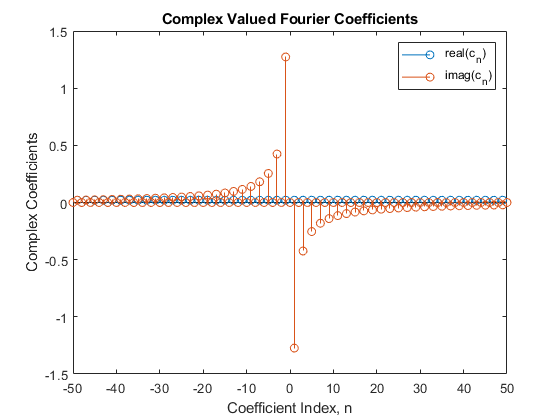

idx = 1;
c = zeros(1,2*N+1);
for n = -N:N
    expTerm = exp(-1i*2*pi*t*n/T);
    c(idx) = (Ts/T)*sum(f .* expTerm);
    idx = idx + 1;
end

stem(-N:N, real(c))
hold on
stem(-N:N, imag(c))
hold off
legend('real(c_n)', 'imag(c_n)')
xlabel('Coefficient Index, n')
ylabel('Complex Coefficients')
title('Complex Valued Fourier Coefficients')

### Fourier Series or Synthesis with Complex Coefficients

Let's write Fourier series with complex coefficients. 


$$f_s \left(t\right)=\sum_{n=-N}^N c_n e^{\left(\frac{j2\pi \textrm{nt}}{T}\right)}$$


f_s = zeros(size(t));
idx = 1;
for n=-N:N
    expTerm = exp(1i*2*pi*t*n/T);
    f_s = f_s  + c(idx)*expTerm;
    idx = idx + 1;
end

plot(t,f)
hold on
plot(t,f_s)

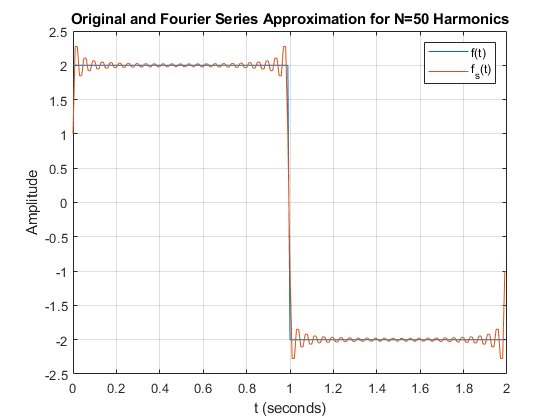

hold off
grid on
legend('f(t)', 'f_s(t)')

xlabel('t (seconds)')
ylabel('Amplitude')
legend('f(t)', 'f_s(t)')
title(sprintf('Original and Fourier Series Approximation for N=%d Harmonics',N))

The warning is due to numerical precision errors. All values are less than 1e-16.

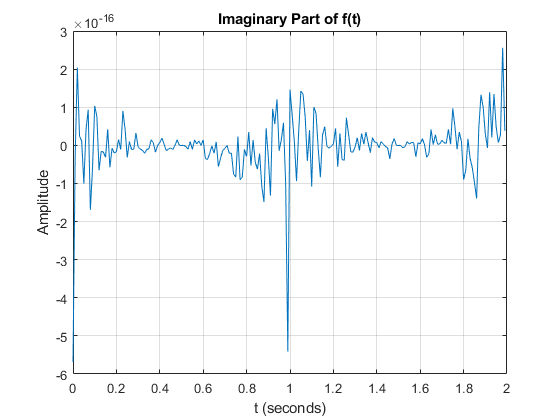

plot(t,imag(f_s))
grid on
xlabel('t (seconds)')
ylabel('Amplitude')
title('Imaginary Part of f(t)')

## Fourier Series Analysis of ECG Signal

ECG signals help us visualize heart beats, which are periodic signals. We can analyze these signals using Fourier series. I downloaded a ECG signal from [Physionet.org](https://physionet.org/). The signal is sampled at 720 Hz. 

load aami3am.mat
Fs = 720;
tecg = 0:1/Fs:(length(val)-1)/Fs;

plot(tecg, val)
grid on
xlabel('t (seconds)')
ylabel('Amplitude')
title('ECG Signal')

First, we need to estimate the period of this signal. Use the data curser to mark two consecutive peaks. Select the "Data Cursor" tool, then click on a peak. Live Script shows you the code you need to add the data tip. I copied that code in the following.

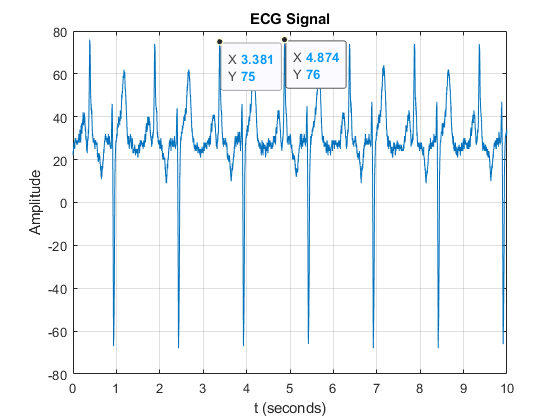

ax = gca;
chart = ax.Children(1);
datatip(chart,3.381,75);
ax = gca;
chart = ax.Children(1);
datatip(chart,4.874,76);

The difference between the two tips is the period. 

Theart = 4.874-3.381;
BPM = 60/Theart  % Beats per minute

BPM = 40.1875

tperiod = round(3.381*Fs):round(4.874*Fs);
valT = val(tperiod);

Calculate the Fourier series coefficients for different values of N. Store the results in a matrix. Append the original signal as the last row.

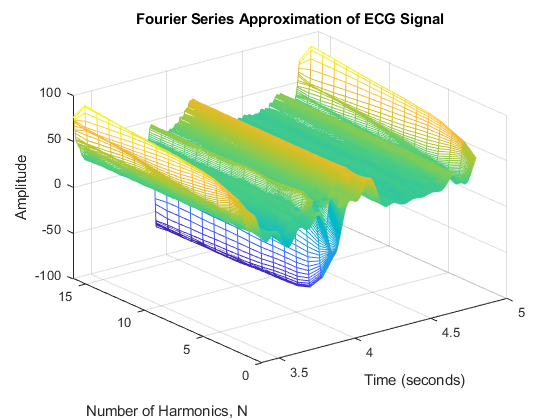

valT_mat = zeros(16,size(valT,2));
idx = 1;
for N=10:10:150
    [~,~,valT_s] = fourier_real(valT, Theart, 1/Fs, N);
    valT_mat(idx,:) = valT_s;
    idx = idx + 1;
end
valT_mat(idx,:) = valT;
    
mesh(tperiod/Fs, 1:16, valT_mat)
xlabel('Time (seconds)')
ylabel('Number of Harmonics, N')
zlabel('Amplitude')
title('Fourier Series Approximation of ECG Signal')

At about N=50, we get a very good approximation. Plot the Fourier coefficients for N=0:150. After about N=50, there are no significant contributions, which matches the previous result.

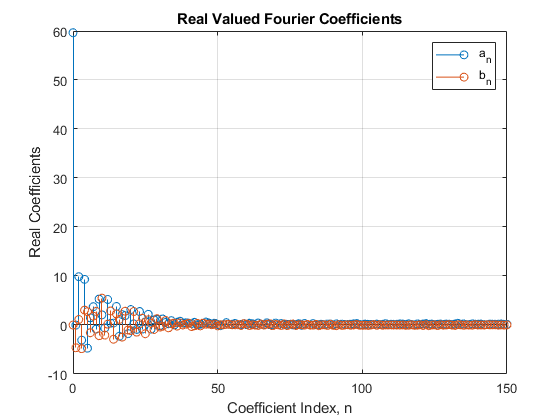

[a,b] = fourier_real(valT, Theart, 1/Fs, 150);
stem(0:150,a)
hold on
stem(0:150,b)
hold off
grid on
xlabel('Coefficient Index, n')
ylabel('Real Coefficients')
legend('a_n', 'b_n')
title('Real Valued Fourier Coefficients')

## Appendix A: Logical Indexing in MATLAB

In MATLAB there are two ways to index a vector. This is computer engineering way of saying "accessing a valuw in a vector". Let's first create a vector.

    a = 1:5

a =      1     2     3     4     5


We can get the 2nd element of a by typing

    a(2)

ans = 2

What if I want to find values of a that are less than 3. How can I find the indices of those elements? Let's try typing the mathematical expression

    a < 3

ans = 1×5 logical array
   1   1   0   0   0


Now I have a logical array whoes values are true for the indices where values of a is less than 3. I can use this array as the index and see what happens.

    a(a<3)

ans =      1     2


MATLAB returned the elements of a, where a<3 is true. Or, we extracted the values of a, where a is less than 3. We can use logical indexing to create piecewise functions.

## Appendix B: Efficient Implementation of Complex Coefficient Fourier Series

    N = 5    % Number of harmonics

N = 5

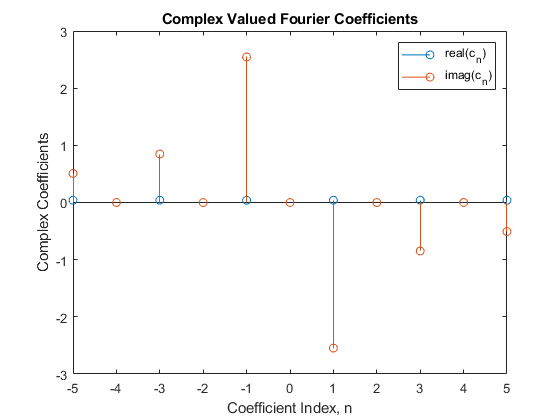

    idx = 1;
    c = zeros(1,N+1);
    for n = 0:N
        expTerm = exp(-1i*2*pi*t*n/T);
        c(idx) = (2*Ts/T)*sum(f .* expTerm);
        idx = idx + 1;
    end
    
    stem(-N:N, [real(c(end:-1:2)) real(c)])
    hold on
    stem(-N:N, [-imag(c(end:-1:2)) imag(c)])
    hold off
    legend('real(c_n)', 'imag(c_n)')
    xlabel('Coefficient Index, n')
    ylabel('Complex Coefficients')
    title('Complex Valued Fourier Coefficients')

### Fourier Series or Synthesis with Complex Coefficients

Let's write Fourier series with complex coefficients.


$$f_s \left(t\right)=\sum_{n=-N}^N c_n e^{\left(\frac{j2\pi \textrm{nt}}{T}\right)}$$


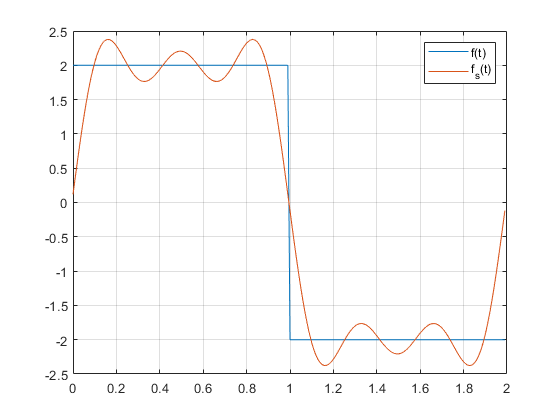

    f_s = (1/2)*c(1)*ones(size(t));  % Start with c_0
    for n=1:N
        expTerm = exp(1i*2*pi*t*n/T);
        f_s = f_s  + (1/2)*c(n +1)*expTerm + (1/2)*conj(c(n +1))*conj(expTerm);
    end
    
    plot(t,f)
    hold on
    plot(t,f_s)
    hold off
    legend('f(t)', 'f_s(t)')
    grid on

## Appendix C: Helper Functions

    function [a,b,f_s] = fourier_real(f, T, Ts, N)
    %fourier_real Fourier series with real coefficients
    %  [A,B,FUNSYN] = fourier_real(FUN, T, TS, N) calculates Fourier series
    %  representation of FUN using real coefficients. T is the period of the
    %  signal FUN, TS is the sampling period and N is the number of harmonics.
    %  A and B are the cosine and since coefficients, respectively. FUNSYN is
    %  the synthesized signal using N harmonics.
    
    t = 0:Ts:(length(f)-1)*Ts;
    
    idx = 1;                    % Index for a and b vectors
    a = zeros(1,N+1);           % Preallocate for speed
    b = zeros(1,N+1);           % Preallocate for speed
    for n = 0:N
        cosTerm = cos(2*pi*t*n/T);
        sinTerm = sin(2*pi*t*n/T);
        a(idx) = (2*Ts/T)*sum(f .* cosTerm);    % Integrate from t = 0 to T
        b(idx) = (2*Ts/T)*sum(f .* sinTerm);    % Integrate from t = 0 to T
        idx = idx + 1;
    end
    
    % Initialize f_s with a_0, which is the first value in a vector
    f_s = (a(1)/2)*ones(size(t));
    for n=1:N
        cosTerm = cos(2*pi*t*n/T);
        sinTerm = sin(2*pi*t*n/T);
        % Accumulate f_s with the nth term. Since n starts from 0, we use index
        % n+1 in MATLAB, which uses 1-based indexing.
        f_s = f_s  + a(n +1)*cosTerm + b(n +1)*sinTerm;
    end
    end
